# Práctica 3: Localización EKF y Mapeo - Rodríguez, Maximiliano

## Filtro de Kalman Extendido (EKF)

    El EKF funciona igual que el filtro de Kalman, pero en lugar de asumir que el sistema se comporta linealmente, **linealiza las funciones no lineales** alrededor del estado actual usando derivadas (Jacobianos).

    Supongamos que el sistema se describe con:

- **    Función de transición de estado** (no lineal): $x_t =g\left(x_{t-1} ,u_t \right)+w_t$

- **    Función de observación** (no lineal): $z_t =h_t +v_t$

    Donde $w_t$ y $v_t$ son ruidos gaussianos.

    El EKF se puede dividir en dos pasos, los cuales son predicción y corrección.

### Predicción

    El EFK realiza la predicción de la siguiente manera:

- Predice el nuevo estado: $\bar{\mu_t } =g\left(\mu_{t-1} ,u_t \right)$

- Calcula el jacobiano $G_t =\frac{\;\partial g\left(u_t ,\mu {\;}_{t-1} \right)}{\partial x_{t-1} }$

- Calcula el jacobiano $V_{t\;} =\frac{\partial g\left(u_t ,\mu_{t-1} \right)}{\partial u_t }$

- Predice la covarianza $\bar{\Sigma_t } =G_t \;\Sigma_{t-1} G_t^T +V_t M_t V_t^T$ donde $M_t$ es una covarianza que modela el ruido que hay en las acciones de control.

    En orden de implementar este filtro, se calculó la matriz jacobiana $G_t$ de la funcion de movimiento $g$ según el Modelo de Odometría. Este modelo tiene las siguientes ecuaciones:


$$\begin{array}{l}
x_{t\;} =x_{t-1} +t\cdot \cos \left(\theta_{t-1} +r_1 \right)\\
y_t =y_{t-1} +t\cdot \sin \left(\theta_{t-1} +r_1 \right)\\
\theta_t =\theta_{t-1} +r_{1\;} +r_2 
\end{array}$$


    Donde

- $\left(x,y,\theta \;\right)$ es el estado del robot.

- $u=\left(r_1 ,t,r_2 \right)$ es la acción de control.

    Según lo definido anteriormente, podemos calcular la matriz $G_t \;$:


$$G_t =\;\left\lbrack \begin{array}{ccc}
\frac{\partial g_1 }{\partial x} & \frac{\partial g_1 }{\partial y} & \frac{\partial g_3 }{\partial \theta }\\
\frac{\partial g_2 }{\partial x} & \frac{\partial g_2 }{\partial y} & \frac{\partial g_2 }{\partial \theta }\\
\frac{\partial g_3 }{\partial x} & \frac{\partial g_3 }{\partial y} & \frac{\partial g_3 }{\partial \theta }
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & -t\cdot \sin \left(\theta +r_1 \right)\\
0 & 1 & t\cdot \cos \left(\theta +r_1 \right)\\
0 & 0 & 1
\end{array}\right\rbrack$$


    De la misma manera, se calculó $V_t \;$:


$$V_t =\;\left\lbrack \begin{array}{ccc}
-t\cdot \sin \left(\theta +r_1 \right) & \cos \left(\theta +r_1 \right) & 0\\
t\cdot \cos \left(\theta +r_1 \right) & \sin \left(\theta +r_1 \right) & 0\\
1 & 0 & 1
\end{array}\right\rbrack$$


    Se implementó el algoritmo de la siguiente manera:

function [mu_, sigma_] = prediction_step(mu, sigma, u)
    % Updates the belief, i. e., mu and sigma, according to the motion model
    %
    % u: odometry reading (r1, t, r2)
    % mu: 3 x 1 vector representing the mean (x, y, theta) of the normal distribution
    % sigma: 3 x 3 covariance matrix of the normal distribution

    % Compute the noise-free motion. This corresponds to the function g, evaluated
    % at the state mu.
    theta = mu(3);
    mu_ = mu + [u.t * cos(theta + u.r1);
           u.t * sin(theta + u.r1);
           u.r1 + u.r2];

    % Compute the Jacobian of g with respect to the state
    G = [1, 0, -u.t * sin(theta + u.r1);
         0, 1,  u.t * cos(theta + u.r1);
         0, 0,  1];

    V = [-u.t*sin(theta+u.r1), cos(theta+u.r1), 0;
          u.t*cos(theta+u.r1), sin(theta+u.r1), 0;
          1,                    0,              1];

    % Motion noise
    Q = [0.2, 0, 0; 
        0, 0.2, 0; 
        0, 0, 0.02];

    sigma_ = G * sigma * G.' + V*Q*V.';
end

### Corrección

    El EKF realiza la corrección de la siguiente manera:

-    Estima $\hat{z_t \;} =h\left(\mu_t \right)$

-    Calcula el jacobiano $H_t =\frac{\partial h}{\partial \mu }$

-    Calcula $K_t =\bar{\Sigma_t } H_t^T {\left(H_t \;\bar{\Sigma_t } \;H_t^T +Q_t \right)}^{-1}$

-    Actualiza $\mu =\bar{\mu_t } +K_t \;\left(z_t -\hat{z_t } \right)$

-    Actualiza $\Sigma_{t\;} =\left(I-K_t H_t \right)\bar{\;\Sigma_t }$

    Luego, para implementar el algoritmo, se calculó la matriz jacobiana $H_t \;$de la función de medición $h$ sin ruido de un sensor que solo mide distancia.

    Sabiendo que la función de medición mide la distancia al landmark:


$$h\left(\mu \right)=\sqrt{\;{\left(m_x -x\right)}^2 +{\left(m_y -y\right)}^2 }$$



$$\to H_t =\left\lbrack \begin{array}{ccc}
\frac{\partial h}{\partial x} & \frac{\partial h}{\partial y} & \frac{\partial h}{\partial \theta }
\end{array}\right\rbrack \;$$


    Si se define $q={\left(m_x -x\right)}^2 +{\left(m_y -y\right)}^{2\;} \to h\left(u\right)=\sqrt{q}$, entonces:

    
$$H_t =\left\lbrack \begin{array}{ccc}
\frac{-\left(m_x -x\right)}{\sqrt{q}} & \frac{-\left(m_y -y\right)}{\sqrt{\;q}} & 0
\end{array}\right\rbrack \;$$


    Luego, $R_t =0\ldotp 5\;$ya que el sensor solo mide rango.

    Se implementó el algoritmo de la siguiente manera:

function [mu_, sigma_] = correction_step(mu, sigma, z, l)
    mu_ = mu;
    sigma_ = sigma;

    R = 0.5^2;  % Varianza escalar, ya que sólo hay rango

    for i = 1:length(z)
        j = z(i).id;
        mx = l(j).x;
        my = l(j).y;

        dx = mx - mu_(1);
        dy = my - mu_(2);
        q = dx^2 + dy^2;

        % Medición esperada 
        z_hat = sqrt(q);

        % Jacobiano de h respecto al estado
        H = [-dx / sqrt(q), -dy / sqrt(q), 0];  % 1x3

        % Kalman
        S = H * sigma_ * H.' + R;     
        K = sigma_ * H.' / S;        

        z_real = z(i).range;
        innovation = z_real - z_hat;

        % Corrección
        mu_ = mu_ + K * innovation;
        mu_(3) = atan2(sin(mu_(3)), cos(mu_(3)));  % Normalizar theta
        sigma_ = (eye(3) - K * H) * sigma_;
    end
end

Se obtuvo el siguiente recorrido:

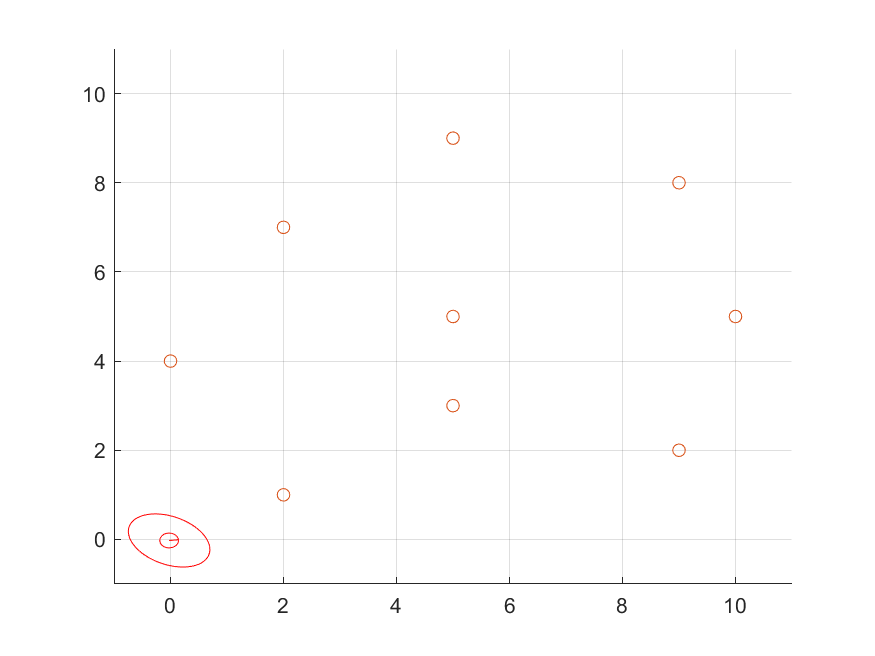

## Mapeo con poses conocidas

    Se requirió lo siguiente:

*    "Un robot debe construir un mapa de grilla de ocupación (celdas c0, . . . , cn) de un entorno unidimensional usando una secuencia de mediciones de un sensor de distancia. Asumir el siguiente modelo de sensor: cada celda de la grilla con una distancia menor que la distancia medida se asume ocupada con una probabilidad de p = 0,3. Cada celda más allá de la distancia medida se asume ocupada con una probabilidad de p = 0,6. Las celdas ubicadas a más de 20cm por detrás de la distancia medida no cambian su probabilidad de ocupación."*

    Para calcular el mapa de grilla de ocupación resultante, se utilizó el modelo de sensor inverso. Primero se inicializaron los valores necesarios para el algoritmo:

c = 0:10:200;  % Vectores de posiciones en el espacio (de 0 a 200, con paso de 10)
mediciones = [101, 82, 91, 112, 99, 151, 96, 85, 99, 105];  % Mediciones del sensor 1
mediciones2 = [101, 99, 97, 102, 99, 100, 96, 104, 99, 105]; % Mediciones del sensor 2
l = zeros(1,21);  % Inicializa un vector para almacenar los valores logarítmicos de la creencia (l) para cada posición.

    La variable `l `guarda los log-odds, que permite actualizar creencias de forma aditiva. El log-odds se define como:

$l=\log \left(\frac{p}{1-p}\right)$, y la inversa es $p=\frac{1}{1+e^{-l} }$

    Para cada celda deberemos actualizar $l_{\mathrm{nueva}} =l_{\mathrm{anterior}} +l_{\mathrm{sensor}}$ donde $l_{\mathrm{sensor}}$ se comporta de la siguiente manera:

- **ocupada**: log-odds de 0.6 → `log(0.6/1-0.6) `

- **libre**: log-odds de 0.3 → `log(0.3/1-0.3)`

- **no observada**: no se actualiza

    Luego, se calcula la creencia para el primer sensor:

for i = 1:size(mediciones,2)
    for j = 1:size(c,2)
        if c(j) >= mediciones(i) - 20 && c(j) <= mediciones(i) + 20
            l(j) = l(j) + inv_sensor_model(mediciones(i), c(j));
        end
    end
end

m = 1 - 1./(1 + exp(l));

En este bloque, el código itera sobre todas las mediciones del primer sensor (`mediciones`).

Para cada medición, se compara con las posiciones en `c`. Si la posición `c(j)` está dentro de un rango de 20 unidades alrededor de la medición (`mediciones(i)`), se calcula el valor de creencia logarítmica utilizando el modelo de sensor inverso `inv_sensor_model`.

Una vez terminado el ciclo `for, `se crea la función `inv_sensor_model `para que devuelva el log-odd de la forma que habiamos descripto anteriormente.

function l = inv_sensor_model(medicion, posicion)
    if (posicion < medicion)
        l = log(0.3/(1-0.3));
    else
        l = log(0.6/(1-0.6));
    end
end

Se obtuvieron los siguientes beliefs: